load ('NeurotechsmilefrownangryblinkS1filt0p5notch56t64epochs.mat')
originalEEG = EEG

originalEEG = struct with fields:
             setname: 'smilefrownblinksam filt epochs'
            filename: ''
            filepath: ''
             subject: ''
               group: ''
           condition: ''
             session: []
            comments: [2×39 char]
              nbchan: 2
              trials: 409
                pnts: 1000
               srate: 250
                xmin: -0.5000
                xmax: 3.4960
               times: [1×1000 double]
                data: [2×1000×409 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×2 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'common'
               event: [1×1746 struct]
             urevent: []
    eventdescription: {''  ''  ''  ''}
               epoch: [1×409 struct]
    epochdescription: {}
              reject: [1×1 struct]
               stats: [1×1 struct]



smileCat = (EEG.epochlabelscat=="S pressed");
sum(smileCat)

ans = 151

angryCat = (EEG.epochlabelscat=="A pressed");
sum(angryCat)

ans = 57



if sum(smileCat)>sum(angryCat)
    num_trials_per_cond = sum(angryCat)
else
    num_trials_per_cond = sum(smileCat)
end

num_trials_per_cond = 57

num_trials_per_cond

num_trials_per_cond = 57


idx_trialstokeep = [find(EEG.epochlabelscat=="S pressed",num_trials_per_cond) find(EEG.epochlabelscat=="A pressed",num_trials_per_cond)]

idx_trialstokeep =      7    10    11    13    14    17    18    20    21    22    23    24    32    33    34    35    40    41    43    44    49    50    51    52    58    59    60    72    73    74    75    76    77    78    79    80    81    82    91    93    95    97    99   101   103   104   105   106   107   108


idx_trialstokeep = sort(idx_trialstokeep);

EEG.data = originalEEG.data(:,:,idx_trialstokeep); %Trim the data
EEG.epochlabelscat = originalEEG.epochlabelscat(idx_trialstokeep); %Trim the list of labels
EEG.epochlabelscat = removecats(originalEEG.epochlabelscat(idx_trialstokeep)); %Remove extra categories
EEG.trials = sum(idx_trialstokeep);

for channel = 1:size(EEG.data,1)  
    %Trial by trial baseline removal
    EEG.data(channel,:, :) = EEG.data(channel,:, :) - mean(EEG.data(channel,:, :),2);
end

rng(101); % Do this to theoretically get the same split each time (not important for this situation, but important in my lab.)

% Hold out 20% of the data for the testing set.
ttpart = cvpartition(EEG.epochlabelscat,'HoldOut',.20);

% Set up table of data that includes the trial labels
traindata = table(EEG.epochlabelscat(ttpart.training)','VariableNames',{'labels'});

testdata = table(EEG.epochlabelscat(ttpart.test)','VariableNames',{'labels'});


includedchannels = [1 2]; %channels to included, this will calculate features for each separately 
timewindowforfeatures = [0 2000]; %start and stop in ms. If timepoints don't line up, this will select a slightly later time
timewindowepochidx = (find(EEG.times>=timewindowforfeatures(1),1)):(find(EEG.times>=timewindowforfeatures(2),1));

tempdata = traindata;
idxt = ttpart.training;

for ch = includedchannels
    clear mydata;
        mydata = squeeze(EEG.data(ch,timewindowepochidx,idxt));
        mydata = mydata./1000 %converting data from mV (what I think the data started as, need to double check)
end

mydata = 501×92 single matrix
   -0.0272   -0.0110    0.0587   -0.0309    0.0518   -0.0316    0.0188    0.0780    0.1107    0.0260    0.1671    0.0111    0.0243   -0.0403    0.0195    0.0257    0.0025    0.1048   -0.0463   -0.0705    0.0135   -0.0029    0.0295    0.0159    0.0208    0.0554    0.0335    0.0363   -0.0279   -0.6457    0.0585    0.1613    0.0259    0.0507    0.0555   -0.0847    0.0188    0.3746   -0.1969    0.0403    0.2022    0.1680   -0.1488    0.2470    0.0341   -0.0213    0.0171   -0.6494   -0.2827   -0.1742
   -0.0264   -0.0080    0.0598   -0.0274    0.0579   -0.0267    0.0242    0.0727    0.1155    0.0280    0.1599    0.0090    0.0315   -0.0435    0.0240    0.0260    0.0043    0.1237   -0.0533   -0.0762    0.0020   -0.0067    0.0288    0.0121    0.0098    0.0459    0.0354    0.0212   -0.0302   -0.6414    0.0518    0.1504    0.0276    0.0489    0.0529   -0.0905    0.0194    0.3635   -0.1822    0.0499    0.2045    0.1572   -0.1554    0.2470    0.0203   -0.0339    0.024

mydata = 501×92 single matrix
    0.0007   -0.0357   -0.0148   -0.0956   -0.0393   -0.0347   -0.0048   -0.0142    0.0097   -0.0088    0.0540   -0.0256   -0.0312    0.0496   -0.0104   -0.0776    0.0157    0.0044    0.0331   -0.0132   -0.0393    0.0038   -0.0096   -0.0187   -0.0164   -0.0388   -0.0298    0.0244    0.0015   -0.2995    0.0345    0.1154   -0.0053   -0.1416    0.0723   -0.1563   -0.0079    0.0879   -0.0187   -0.0091   -0.0709   -0.0122   -0.0141   -0.0404   -0.0212   -0.0094   -0.0580    0.1302    0.1510    0.2048
    0.0014   -0.0349   -0.0130   -0.0970   -0.0439   -0.0351   -0.0032   -0.0194    0.0138   -0.0073    0.0374   -0.0346   -0.0319    0.0388   -0.0045   -0.0745   -0.0026   -0.0059    0.0272   -0.0176   -0.0391   -0.0012   -0.0135   -0.0163   -0.0169   -0.0301   -0.0317    0.0324    0.0044   -0.3023    0.0330    0.1095   -0.0055   -0.1431    0.0961   -0.1470   -0.0011    0.0907   -0.0183   -0.0147   -0.0761   -0.0061   -0.0178   -0.0400   -0.0139   -0.0183   -0.061

[dataPoints, trialNum] = size(mydata)

dataPoints = 501

trialNum = 92

yk = zeros(dataPoints, trialNum);
trialMean = mean(mydata)

trialMean = 1×92 single row vector
    0.0092   -0.0038   -0.2359    0.0082   -0.1041   -0.0025    0.0050    0.0284    0.0600   -0.1367   -0.0329   -0.0018    0.0065    0.0221   -0.0087   -0.0059   -0.0134   -0.0454   -0.0073   -0.0111   -0.0032    0.0030    0.0029   -0.0014   -0.0031    0.0008    0.0018    0.0302   -0.0983    0.0617   -0.0280    0.1418   -0.2368    0.0298   -0.0248    0.0186   -0.0201    0.0013   -0.0091   -0.0251    0.0171   -0.0062   -0.0183    0.0047   -0.0169    0.0001    0.0300   -0.0751   -0.0161   -0.0710


yk = (cumsum((mydata)-mean(mydata)));

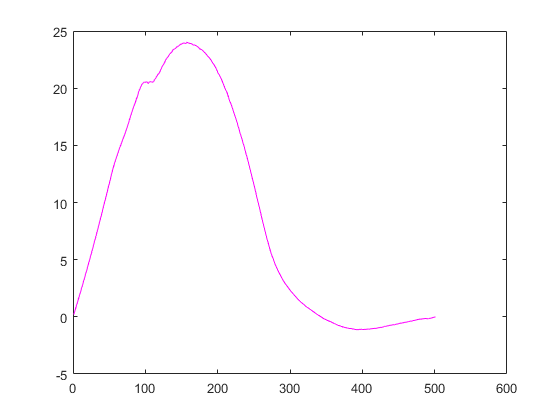

figure
plot(yk(:,78), 'm')
hold on

plot(yk2(:,78), 'c')

Undefined function or variable 'yk2'.

hold on
plot(mydata(:,78), 'k')
hold off
trialMean(78)

w.totaltimewindow = [1 501]; %start and stop data points, the size of each trial. If points don't line up, this will select a slightly later time
%timetimewindowepochidx = (find(EEG.times>=timewindowforfeatures(1),1)):(find(EEG.times>=timewindowforfeatures(2),1));

w.timewindowbinsize = [4 5 10 20 25 50]; %This is where you enter the different bin sizes that will be looped through. They should ideally divide into an equal number of data points
w.timewindowoverlap = 0; %128 for another paper

% includedchannels = 1:2;
% for ch = includedchannels    
%     for  tw = 1:size(w.alltimewindowsforfeatures,2)
%                     timewindowforfeatures = w.alltimewindowsforfeatures(:,tw);
%                     timewindowepochidx = (find(EEG.times>=timewindowforfeatures(1),1)):(find(EEG.times>=timewindowforfeatures(2),1));
%                     epochData = squeeze(EEG.data(ch,:,idxt)),2;
%     end
% end

for bin = 1:(size(w.timewindowbinsize,2))
    
    w.starttimes = w.totaltimewindow(1):(w.timewindowbinsize(bin)-w.timewindowoverlap):w.totaltimewindow(2);
    w.endtimes = (w.totaltimewindow(1)-1+w.timewindowbinsize(bin)):(w.timewindowbinsize(bin)-w.timewindowoverlap):w.totaltimewindow(2);
    if w.totaltimewindow(2) - w.starttimes(end) <= w.timewindowoverlap %if increment is smaller than the overlap window
        w.starttimes(end) = []; %then remove the last one (avoids indexing problem, plus you've already used this data)
    end
    if length(w.starttimes) > length(w.endtimes)
        w.endtimes = [w.endtimes w.totaltimewindow(2)];
        warning('The timewindowbinsize does not split evenly into the totaltimewindow, last window will be smaller')
        w.endtimes - w.starttimes
    end
    w.alltimewindowsforfeatures = [w.starttimes; w.endtimes];%(:,1) for first pair
    
    xval = [1:w.timewindowbinsize(bin)]
    
    for trial = 1:trialNum
        
            for L = 1:(w.totaltimewindow(2)/w.timewindowbinsize(bin))
                 databin = yk((w.starttimes(L):w.endtimes(L)), trialNum);
                 if L == 1
                    epochData = databin;
                 else
                    epochData = cat(2, epochData, databin); 
                 end
                
                epochData = [epochData databin];
            end
            
        if trial == 1
            epochTrial = epochData;
        else
            epochTrial = cat(3, epochTrial, epochData); 
        end
        
        for loop = 1:(w.totaltimewindow(2)/w.timewindowbinsize(bin))
            coeff(loop,:,trial) = polyfit(xval,epochTrial(1:(w.timewindowbinsize(bin)),loop,trial), 1);
            
            singleYn = polyval(coeff(loop,:,trial), xval);
            if loop == 1
                binYn = singleYn;
            else
                binYn = cat(2, binYn, singleYn); 
            end
        end
        
        if trial == 1
                yn = binYn;
            else
                yn = cat(3, yn, binYn); 
        end
    end
    
    squeeze(yn)
    yk = yk(1:(size(yn,2)),:) % When testing, yk ended up one row smaller than yn, so this makes yk and yn the same dimensions
    singleFn  = sqrt((sum((yk - squeeze(yn)).^2)/(size(yk,1))));
    if bin == 1
                fn = singleFn;
            else
                fn = cat(3, fn, singleFn); 
    end
end

flucProfiles = squeeze(fn)
logFn = log10(flucProfiles)
logBinSize = log10(w.timewindowbinsize)

figure
plot(logBinSize, logFn(92,:), 'O')
p = polyfit(logBinSize,logFn(92,:),1)
f = polyval(p,logBinSize);
hold on
plot(logBinSize,f,'--r')
title('DFA from trial 92')
xlabel('log10(binSize)')
ylabel('log10(Fn)')
hold off

DFA = (mean((logFn./logBinSize)'))'

eegMFL = (log10(sqrt(sum((diff(mydata)).^2))))'
features = [table(DFA, eegMFL), traindata]